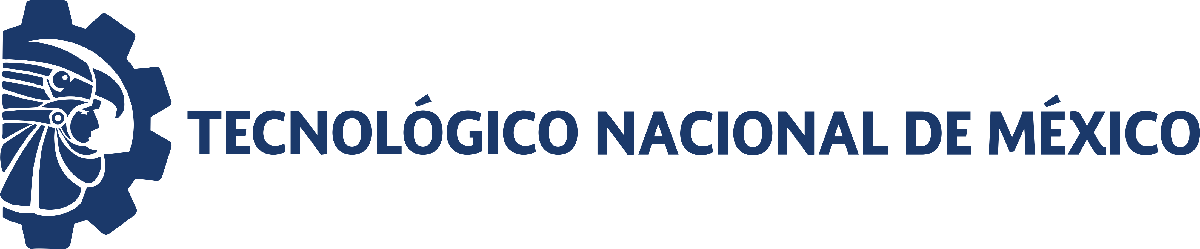                                 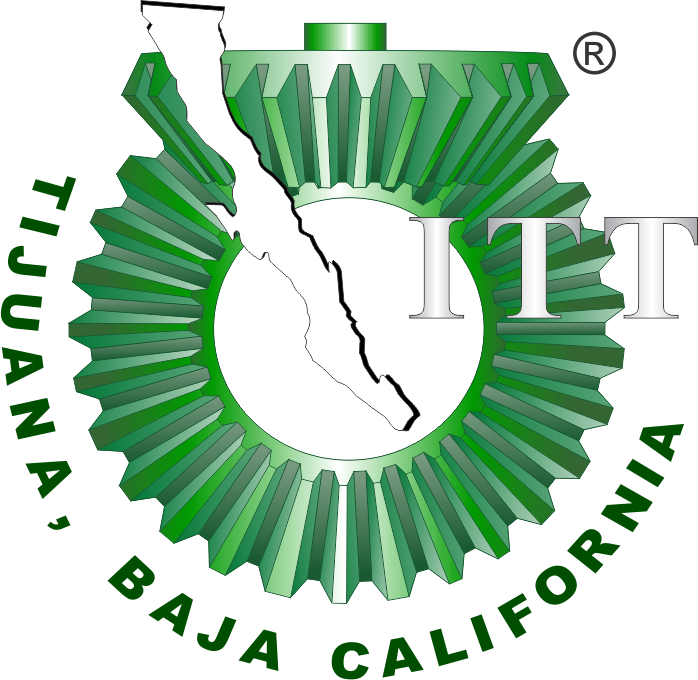

# Práctica cuatro: Modelado y control del sistema cardiovascular mediante el modelo Windkessel

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

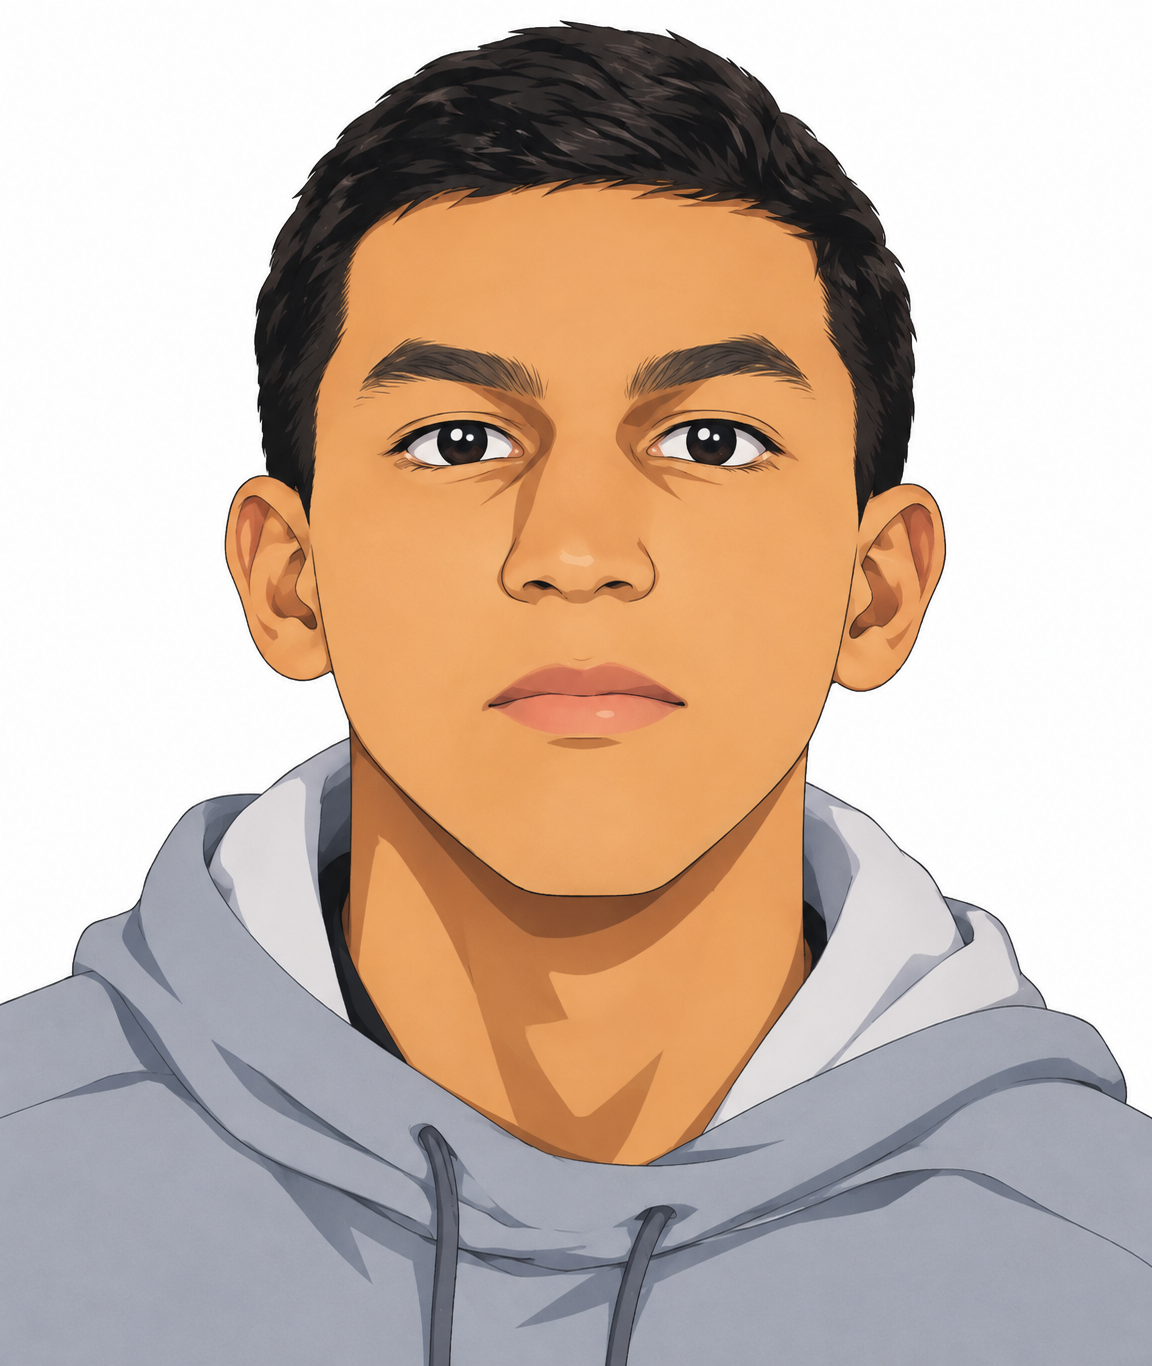

Nombre del alumno: **Sergio Andree Navarro Rodriguez**

Número de control: **23212219**

Correo institucional:** l23212219@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
open_system('sistem')
parameters.StopTime='15';
parameters.Solver = 'ode15s';
parameters.MaxStep = '1e-3';

## Normotenso,Hipotenso,Hipertenso

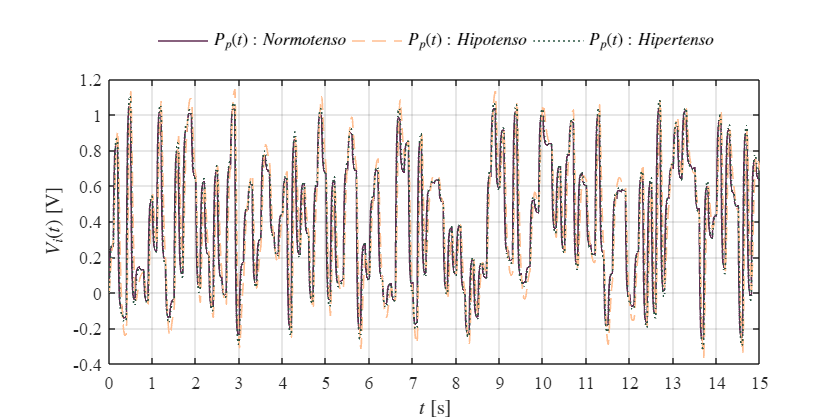

x = sim('sistem',parameters);
t_data=(0:0.1:15);
t= (0:0.001:15);
Pa=interp1(t_data,x.Pa,t,'previous');
writematrix(Pa,'signal.xlsx');
plotSignals(x.t,x.PpN,x.PpL,x.PpH,x.PIDL,x.PIDH,'Individual')

## Hipotenso,Normotenso,Controlador

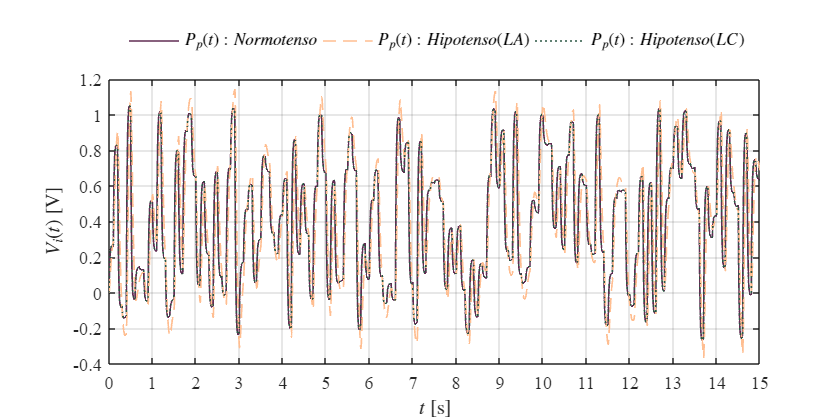

plotSignals(x.t,x.PpN,x.PpL,x.PpH,x.PIDL,x.PIDH,'Hipotenso')

## Hipertenso,Normotenso,Controlador

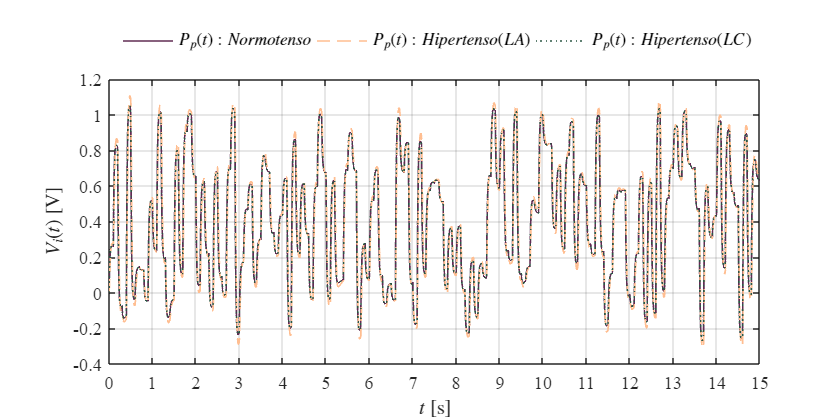

plotSignals(x.t,x.PpN,x.PpL,x.PpH,x.PIDL,x.PIDH,'Hipertenso')

## MODELO EDOS

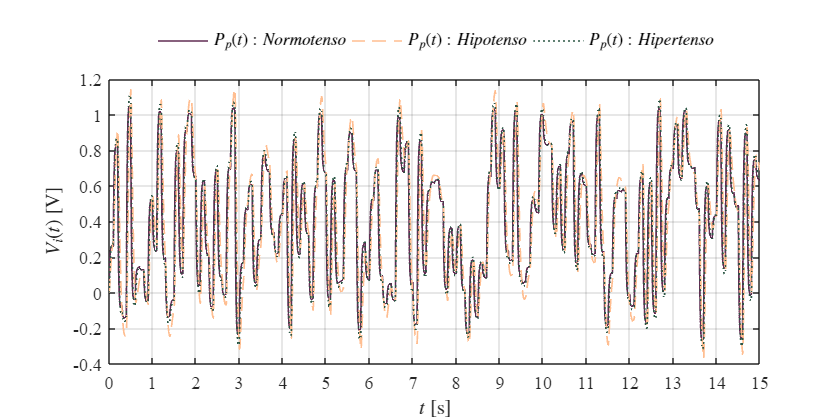

par_hipo=[0.010,0.001,1.000,3.500]; 
par_normo=[0.010,0.001,1.000,1.500]; 
par_hiper=[0.010,0.001,1.000,1.000]; 
PpN=cardio(par_normo,Pa,t);
PpL=cardio(par_hipo,PpN,t);
PpH=cardio(par_hiper,PpN,t);
plotSignals(t,PpN,PpL,PpH,x.PIDL,x.PIDH,'Individual')

function Pp=cardio(par,Pa,t)
Z=par(1);L=par(2);R=par(3);C=par(4);dt=t(2);
n=round(t(end)/dt);

FL=zeros(length(t),1); FL(1)=0;
Pp=zeros(length(t),1); Pp(1)=0;
for i=1:n
    FL(i+1)=FL(i)+(-(1/L)*Pp(i)+(1/L)*Pa(i))*dt;
    Pp(i+1)=Pp(i)+((1/C)*FL(i)-(1/(Z*C)+1/(R*C))*Pp(i)+1/(Z*C)*Pa(i))*dt;
end
end

 

## Función: Respuestas de la simulacion

function plotSignals(t,PpN,PpL,PpH,PIDL,PIDH,signal)
set(figure(),'color','white')
set(gcf,'units','inches','position',[1,1,7,3.5])
set(gca,'fontname','times new roman','fontsize',11)
hold on; grid on;box on;
clr1 = [97,45,83]/255;
clr2 = [255,190,145]/255;
clr3 = [44,87,69]/255;
order = [clr1;clr2;clr3]; colororder(order)

if signal=="Individual"

    plot(t,PpN,'-',t,PpL,'--',t,PpH,':','LineWidth',1,'MarkerSize',5,'MarkerIndices',1:1e3:length(t));
    L=legend('$P_{p}(t): Normotenso$','$P_p(t): Hipotenso$','$P_p(t):Hipertenso$');

    set(L,'interpreter','latex','location','northoutside','orientation','horizontal','Box','off')

    xlabel('$t$ [s]','interpreter','latex')
    ylabel('$V_i(t)$ [V]','interpreter','latex')
elseif signal=="Hipotenso"

    plot(t,PpN,'-',t,PpL,'--',t,PIDL,':','LineWidth',1,'MarkerSize',5,'MarkerIndices',...
        1:1e3:length(t));
    L=legend('$P_{p}(t): Normotenso$','$P_p(t): Hipotenso (LA)$','$P_p(t): Hipotenso (LC)$');

    set(L,'interpreter','latex','location','northoutside','orientation','horizontal','Box','off')

    xlabel('$t$ [s]','interpreter','latex')
    ylabel('$V_i(t)$ [V]','interpreter','latex')
elseif signal=="Hipertenso"

    plot(t,PpN,'-',t,PpH,'--',t,PIDH,':','LineWidth',1,'MarkerSize',5,'MarkerIndices',...
        1:1e3:length(t));
    L=legend('$P_{p}(t): Normotenso$','$P_p(t): Hipertenso (LA)$','$P_p(t): Hipertenso (LC)$');

    set(L,'interpreter','latex','location','northoutside','orientation','horizontal','Box','off')

    xlabel('$t$ [s]','interpreter','latex')
    ylabel('$V_i(t)$ [V]','interpreter','latex')
end
xlim([0 15]); xticks(0:1:15)
ylim([-0.4 1.2]); yticks(-0.4:0.2:1.2)
exportgraphics(gcf,[signal,'_matlab.pdf'],'ContentType','vector')
end